# Why my spectral locus is wrong

3/3/2024

%
% compare 3 datasets
%
cc = ColorConversionClass;
cie2 = CMF_CIE_2deg;
cie10 = CMF_CIE_10deg;

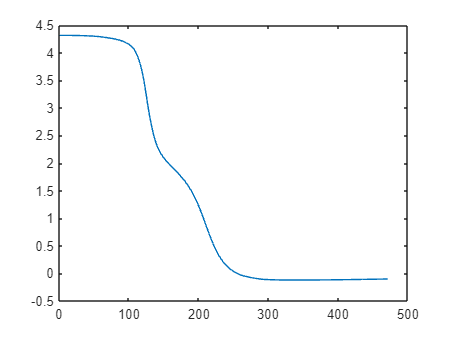

%
% angle of spectral locus
%
clf
plot(cie10.spectral_locus_theta)

cie10.spectral_locus_start_wl_x_y_index

ans =   360.0000    0.1822    0.0200    1.0000


cie10.spectral_locus_end_wl_x_y_index

ans =   701.0000    0.7204    0.2796  342.0000


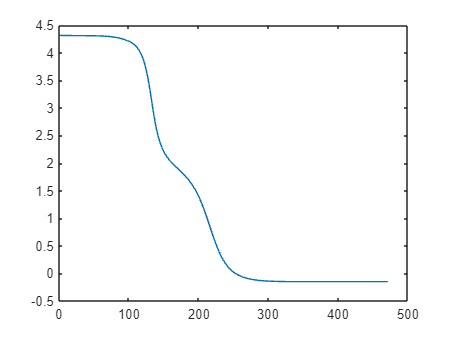

%
% angle of spectral locus
%
clf
plot(cie2.spectral_locus_theta)

cie2.spectral_locus_start_wl_x_y_index

ans =   360.0000    0.1756    0.0053    1.0000


cie2.spectral_locus_end_wl_x_y_index

ans =   767.0000    0.7347    0.2653  408.0000


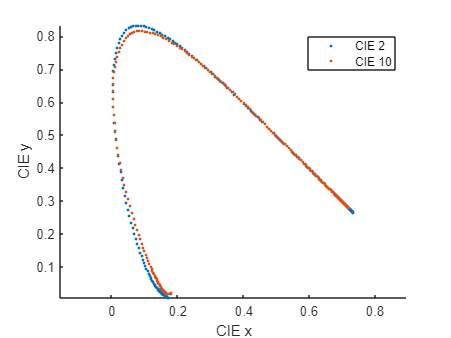

%
% spectral locus comparison
%
figure
hold on
cie2.show_spectral_locus
cie10.show_spectral_locus
axis equal
legend('CIE 2','CIE 10')

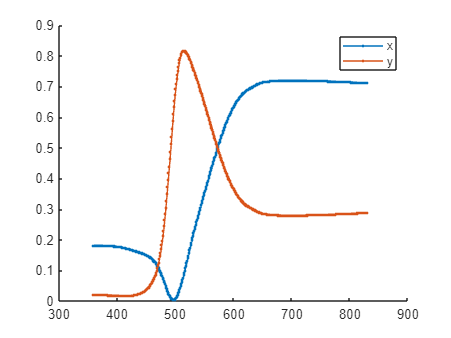

figure
cie10.plot_spectral_locus_xy
legend('x','y')

x = cie10.spectral_locus_xyz(:,2);
y = cie10.spectral_locus_xyz(:,3);
dx = x(2:end) - x(1:end-1);
dy = y(2:end) - y(1:end-1);
ddx = sign(dx);
ddy = sign(dy);
mask = ddx==ddy;
nnz(mask)

ans = 74

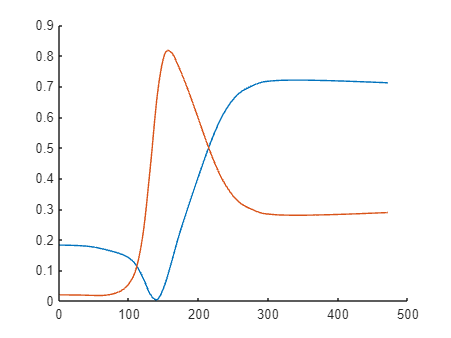

figure
hold on
plot(x)
plot(y)

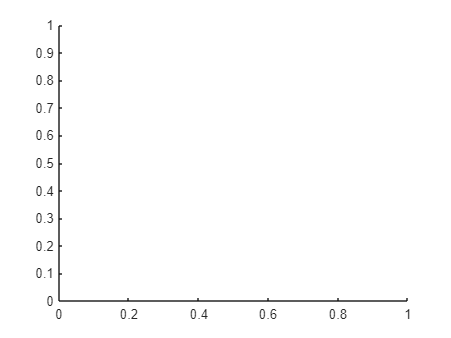

Current plot held


%
% compare cmf-derived spectral locus with the official locus: the same
%
figure
hold

data401_x_y(i:i+1,1),data401_x_y(i:i+1,2)

Index in position 1 exceeds array bounds. Index must not exceed 401.

cie10.show_spectral_locus_official
legend('CIE Calculated','CIE Official')

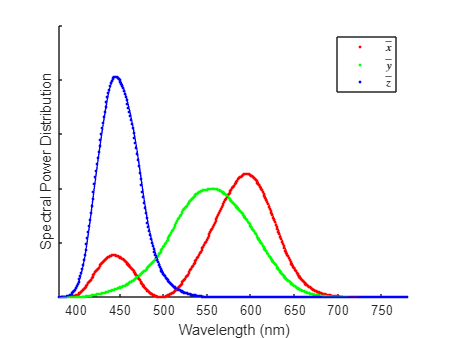

%
% compare the color matching functions
%
figure
%cie2.show_color_matching_functions
cie10.show_color_matching_functions
cc.show_color_matching_functions

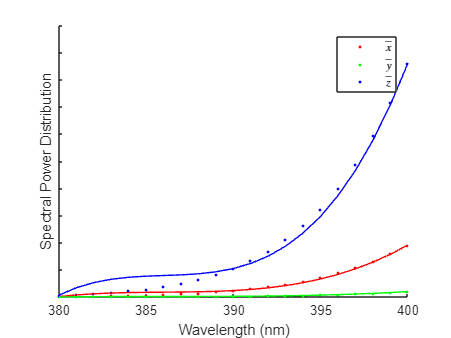

%
% compare the 3 color matching functions
%
figure
%cie2.show_color_matching_functions
cie10.show_color_matching_functions
cc.show_color_matching_functions
axis([380 400 0 0.1])

cc = ColorConversionClass;

%
% create single-spike spectra between [380:10:780]
%
n = 41;                                                          %  ColorConversionClass.spd2XYZ accepts 41 bands only
data41_x_y = zeros(n,2);
for w = 1:41
    sp = zeros(n,1);
    sp(w) = 100000;
    XYZ = cc.spd2XYZ(sp);
    xyz = XYZ ./ sum(XYZ);
    data41_x_y(w,:) = xyz(1:2);
end

data401_x_y = zeros(401,2);
data401_x_y(:,1) = interp1(380:10:780,data41_x_y(:,1),380:780,'spline');
data401_x_y(:,2) = interp1(380:10:780,data41_x_y(:,2),380:780,'spline');

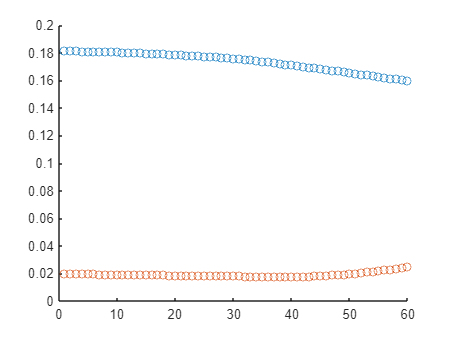

figure
hold on
itv = 1:60;
plot(data401_x_y(itv,:),'o')

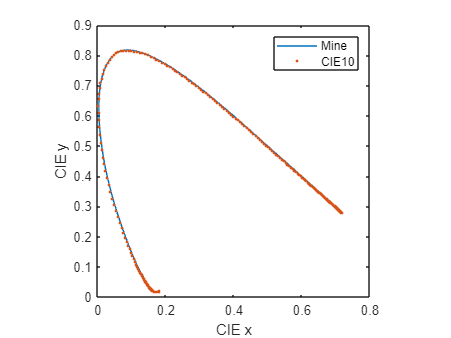

figure
plot(data401_x_y(:,1),data401_x_y(:,2),'-')
cie10.show_spectral_locus
legend('Mine','CIE10')

%
% zoom in
%
figure
plot(data401_x_y(:,1),data401_x_y(:,2),'-')

cie10.show_spectral_locus
axis([0.1 0.2 0 0.2])
legend('Mine','CIE10')

figure
hold on 

plot(data401_x_y(:,1),data401_x_y(:,2),'-')
axis equal
%axis([0.15 0.2 0 0.05])

% https://cie.co.at/datatable/cie-1931-chromaticity-coordinates-spectrum-loci-2-degree-observer
% https://cie.co.at/datatable/cie-1964-chromaticity-coordinates-spectrum-loci-10-degree-observer
cmf = cmf10deg;
plot(cmf(:,2),cmf(:,3),'-')



cmf_x = cmf(:,2) ./ sum(cmf(:,2:4),2);
cmf_y = cmf(:,3) ./ sum(cmf(:,2:4),2);

hold on
plot(cmf_x,cmf_y,'-')
axis equal
%axis([0.15 0.2 0 0.05])
axis([0 1 0 1])

cmf = cmf10deg;
cmf_x = cmf(:,2) ./ sum(cmf(:,2:4),2);
cmf_y = cmf(:,3) ./ sum(cmf(:,2:4),2);


hold on
plot(cmf_x,cmf_y,'-')
axis equal
%axis([0.15 0.2 0 0.05])
axis([0 1 0 1])

legend('My','CIE2','CIE10')

figure
hold on
cmf = cc.cmf_1964;
itv = 1:41;
plot(cmf(itv,1),cmf(itv,2),'-o')
plot(cmf(itv,1),cmf(itv,3),'-o')
plot(cmf(itv,1),cmf(itv,4),'-o')

cmf = cmf2deg;
itv = 1:471;
plot(cmf(itv,1),cmf(itv,2),'-')
plot(cmf(itv,1),cmf(itv,3),'-')
plot(cmf(itv,1),cmf(itv,4),'-')

figure
itv = 1:100;
plot(data401_x_y(itv,:),'-o')


% add the purple line between the first and last points of the
% spectral locus
xy1 = data401_x_y(1,:);
xy2 = data401_x_y(end,:);
pl_x = linspace(xy1(1),xy2(1),200)';
pl_y = linspace(xy1(2),xy2(2),200)';
pl_xy = [pl_x pl_y];

% data401_x_y = [data401_x_y ; pl_xy];


